clc; clear;


brine = importdata("NiceBrineData.txt");
MD = importdata("MegetData.txt");

CP = py.importlib.import_module("CoolProp.CoolProp");

# Behandlet data

P1 = find(MD.textdata(1,2:end) == "P1 Tryk")

P1 = 15

H1 = find(MD.textdata(1,2:end) == "P1 Enthalpy")

H1 = 16


P2 = find(MD.textdata(1,2:end) == "P2 Tryk")

P2 = 20

H2 = find(MD.textdata(1,2:end) == "P2 Enthalpy")

H2 = 21


P3 = find(MD.textdata(1,2:end) == "P3 Tryk")

P3 = 25

H3 = find(MD.textdata(1,2:end) == "P3 Enthalpy")

H3 = 26


P4 = find(MD.textdata(1,2:end) == "P4 Tryk")

P4 = 30

H4 = find(MD.textdata(1,2:end) == "P4 Enthalpy")

H4 = 31


start = 10;

ps_test = MD.data(start:end, [P1,P2,P3,P4]);
hs_test = MD.data(start:end, [H1 H2 H3 H4]);

max_ps = max(ps_test)

max_ps =     2.3469    8.1360    8.1360    2.3469


max_hs = max(hs_test)

max_hs =   395.0915  440.0418  244.5073  244.5073







hlin1 = linspace(max_hs(1),max_hs(2));
hlin2 = linspace(max_hs(2),max_hs(3));
hlin3 = linspace(max_hs(3),max_hs(4));
hlin4 = linspace(max_hs(4),max_hs(1));
hs_test = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(max_ps(1),max_ps(2));
plin2 = linspace(max_ps(2),max_ps(3));
plin3 = linspace(max_ps(3),max_ps(4));
plin4 = linspace(max_ps(4),max_ps(1));
pps_test = [plin1,plin2,plin3,plin4];



# Teoretisk data

% Kølemiddel
ps = 100;
Tfrys = 0;
Tkog = 1200;
middel = "R134a";

% for R134a
Pmin = CP.PropsSI("P","T",170, "Q", 0, middel);
Pmax = CP.PropsSI("P","T", 374, "Q", 1, middel);
Plin = linspace(Pmin, Pmax, ps);


Tsat_l = zeros(size(Plin));

for i = 1:ps-1
    Tsat_l(i) = CP.PropsSI("T", "P", Plin(i), "Q", 0, middel);
end

hl = zeros(size(Plin));
hg = zeros(size(Plin));
sl = zeros(size(Plin));
sg = zeros(size(Plin));

for j = 1:ps-1
    hl(j) = CP.PropsSI("H","P",Plin(j), "Q", 0, middel);
    hg(j) = CP.PropsSI("H","P",Plin(j), "Q", 1, middel);
    sl(j) = CP.PropsSI("S","P",Plin(j), "Q", 0, middel);
    sg(j) = CP.PropsSI("S","P",Plin(j), "Q", 1, middel);
end


% Uden tab

h1 = 389428;
p1 = 1.33e5;

h2 = 467171;
p2 = 8.868*1e5;

h3 = 241463;
p3 = p2;

h4 = h3;
p4 = p1;

%til plot

hlin1 = linspace(h1,h2,ps-1);
hlin2 = linspace(h2,h3,ps-1);
hlin3 = linspace(h3,h4,ps-1);
hlin4 = linspace(h4,h1,ps-1);
hs_teo = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(p1,p2,ps-1);
plin2 = linspace(p2,p3,ps-1);
plin3 = linspace(p3,p4,ps-1);
plin4 = linspace(p4,p1,ps-1);
pps_teo = [plin1,plin2,plin3,plin4]/1e5;

Tr134a = zeros(size(pps_teo));


for k = 1:length(pps_teo)
    Tr134a(k) = CP.PropsSI("T","H",hs_teo(k),"P",pps_teo(k)*1e5, middel);
end
Tr134a;
Trs_teo = Tr134a-273.15;


% Fra opgave

htab1 = 389428;
ptab1 = 1.33e5;

htab2 = 467171;
ptab2 = 8.868e5;

htab3 = 236622;
ptab3 = 8.068e5;

htab4 = htab3;
ptab4 = 1.65e5;

%til plot

hlintab1 = linspace(htab1,htab2,ps-1);
hlintab2 = linspace(htab2,htab3,ps-1);
hlintab3 = linspace(htab3,htab4,ps-1);
hlintab4 = linspace(htab4,htab1,ps-1);
hs_tab = [hlintab1,hlintab2,hlintab3,hlintab4];

plintab1 = linspace(ptab1,ptab2,ps-1);
plintab2 = linspace(ptab2,ptab3,ps-1);
plintab3 = linspace(ptab3,ptab4,ps-1);
plintab4 = linspace(ptab4,ptab1,ps-1);
pps_tab = [plintab1,plintab2,plintab3,plintab4]/1e5;

Tr134a_tab = zeros(size(pps_tab));


for k = 1:length(pps_tab)
    Tr134a_tab(k) = CP.PropsSI("T","H",hs_tab(k),"P",pps_tab(k)*1e5, middel);
end
Tr134a;
Trs_tab = Tr134a_tab-273.15;




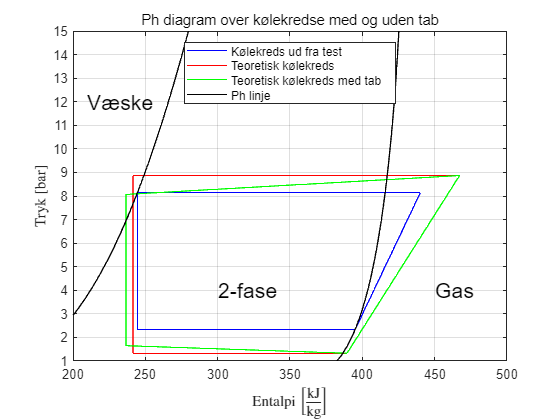


figure

% Kølekreds uden tab
plot(hs_test,pps_test,"b")

xlim([2,5]*1e2)
ylim([1,15])
yticks(1:1:15)


grid("on")

hold on

% Teoretisk uden tab
plot(hs_teo/1e3, pps_teo,"r")

% Teoretisk med tab
plot(hs_tab/1e3, pps_tab,"g")

% PH diagram (ikke log)
plot(hl(1,1:end-1)/1e3,Plin(1,1:end-1)/1e5,"k")
plot(hg(1,1:end-1)/1e3, Plin(1,1:end-1)/1e5,"k")

title("Ph diagram over kølekredse med og uden tab","FontWeight","normal")
ylabel("Tryk [bar]","Interpreter","latex")
xlabel("Entalpi $\left[\mathrm{\frac{kJ}{kg}}\right]$","Interpreter","latex")

text(450, 4,"Gas","FontSize",16)
text(300, 4,"2-fase","FontSize",16)
text(210, 12,"Væske","FontSize",16)

legend("Kølekreds ud fra test","Teoretisk kølekreds","Teoretisk kølekreds med tab","Ph linje","location","north")

hold off

## Brine

ind = 10;



brine_Tbrine = find(brine.textdata(1,2:end) == "Brinetemperatur")

brine_Tbrine = 4

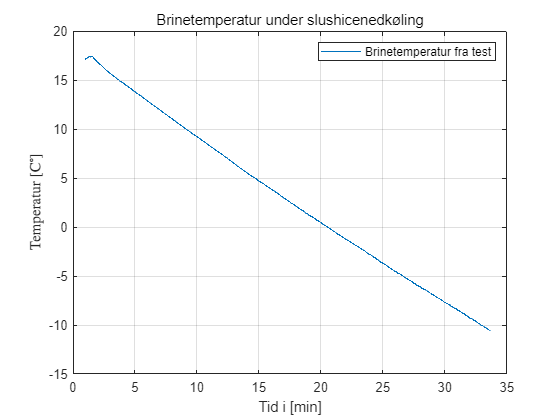

brine_Tbrine = brine.data(ind:end-ind, brine_Tbrine);



figure

plot(xlin, brine_Tbrine(ind:end))

ylabel("Temperatur [C$^\circ$]",Interpreter="latex")


grid("on")
legend("Brinetemperatur fra test","Location","northeast")
title("Brinetemperatur under slushicenedkøling","FontWeight","normal")
xlabel("Tid i [min]")

## Tryk

% MD_lavtryk = find(MD.textdata(1,2:end) == "Tryk lav")
% MD_hojtryk = find(MD.textdata(1,2:end) == "Tryk høj")
% 
% MD_lavtryk = MD.data(ind:end-19, MD_lavtryk) +1;
% MD_hojtryk = MD.data(ind:end-19, MD_hojtryk) +1;
% 
% lps = length(xlin);
% 
% errlin_hoj = zeros(1,lps);
% errlin_lav = zeros(1,lps);
% 
% fejlhoj = 0.008*20;
% fejllav = 0.008*12;
% 
% for i = 1:lps
%     if mod(i,100) == 0
%         errlin_hoj(i) = fejlhoj;
%         errlin_lav(i) = fejllav;
%     else
%         errlin_hoj(i) = 0;
%         errlin_lav(i) = 0;
%     end
% 
% end
% 
% figure
% 
% yyaxis left
% errorbar(xlin, MD_hojtryk, errlin_hoj,"CapSize",0)
% ylabel("Højtryk [bar]")
% ylim([6,8.5])
% 
% yyaxis right
% errorbar(xlin, MD_lavtryk, errlin_lav,"CapSize",0)
% ylabel("Lavtryk [bar]")
% 
% ylim([0,3])
% 
% grid("on")
% legend("Højtryk","Lavtryk","Location","north")
% title("Høj- og lavtryk for slushicedannelse","FontWeight","normal")
% xlabel("Tid i [min]")
% 
% exportgraphics(gcf, "HojLavTrykSlush.png")

## Kondensator temperatur

% 
% T_kond = find(MD.textdata(1,2:end) == "Temperatur efter kompressor")
% T_EPV = find(MD.textdata(1,2:end) == "Temperatur efter kondensator ")
% 
% 
% 
% T2 = MD.data(start:end-start-9, T_kond);
% T3 = MD.data(start:end-start-9, T_EPV);
% 
% lps = length(xlin);
% 
% errlin = zeros(1,lps);
% 
% fejl = 0.9798;
% 
% for i = 1:lps
%     if mod(i,100) == 0
%         errlin(i) = 1;
%     else
%         errlin(i) = 0;
%     end
% 
% end
% 
% figure
% 
% yyaxis left
% errorbar(xlin, T2,errlin,"CapSize",0)
% ylabel("Kondensator temp ind [C$^\circ$]", "Interpreter","latex")
% 
% ylim([20,60])
% 
% yyaxis right
% errorbar(xlin, T3,errlin,"CapSize",0)
% ylabel("Kondensator temp ud [C$^\circ$]", "Interpreter","latex")
% ylim([20,60])
% 
% 
% grid("on")
% legend("Kondensator temp ind","Kondensator temp ud","Location","north")
% title("Kølemiddels temperatur ind og ud af kondensatoren","FontWeight","normal")
% xlabel("Tid i [min]")
% 
% 
% exportgraphics(gcf,"KondTempsSlush.png")

## Fordamper temperatur

% T_komp = find(MD.textdata(1,2:end) == "Temperaturen efter fordamper")
% 
% T_fordamp = find(MD.textdata(1,2:end) == "Temperatur efter EPV")
% 
% T1 = MD.data(start:end-start-9, T_komp);
% T4 = MD.data(start:end-start-9, T_fordamp);
% 
% errlin = zeros(1,lps);
% 
% fejl = 0.9798;
% 
% for i = 1:lps
%     if mod(i,100) == 0
%         errlin(i) = 1;
%     else
%         errlin(i) = 0;
%     end
% 
% end
% 
% 
% figure
% 
% yyaxis left
% errorbar(xlin, T4,errlin,"CapSize",0)
% ylabel("Fordamper temp ind [C$^\circ$]", "Interpreter","latex")
% 
% ylim([-30,20])
% 
% yyaxis right
% errorbar(xlin, T1,errlin,"CapSize",0)
% ylabel("Fordamper temp ud [C$^\circ$]", "Interpreter","latex")
% 
% ylim([-30,20])
% 
% grid("on")
% legend("Fordamper temp ind","Fordamper temp ud","Location","north")
% title("Temperatur ind og ud af fordamperen","FontWeight","normal")
% xlabel("Tid i [min]")
% 
% exportgraphics(gcf,"FordampTempsSlush.png")

## Motortemperatur

% MD_motortemp = find(MD.textdata(1,2:end) == "Motortemperatur");
% 
% MD_motortemp = MD.data(ind:end-19, MD_motortemp);
% 
% errlin = zeros(1,lps);
% 
% fejl = 0.9798;
% 
% for i = 1:lps
%     if mod(i,100) == 0
%         errlin(i) = 1;
%     else
%         errlin(i) = 0;
%     end
% 
% end
% 
% errlin
% 
% figure
% errorbar(xlin, MD_motortemp, errlin,"CapSize",0)
% 
% 
% 
% ylabel("Temperatur [C$^\circ$]",Interpreter="latex")
% 
% 
% grid("on")
% legend("Motortemperatur","Location","north")
% title("Motortemperatur under slushicenedkøling","FontWeight","normal")
% xlabel("Tid i [min]")
% 
% exportgraphics(gcf,"MotorTempsSlush.png")

## Slushicetemperatur

% MD_slushtemp = find(MD.textdata(1,2:end) == "Slush Ice temperatur");
% 
% MD_slushtemp = MD.data(ind:end-19, MD_slushtemp);
% 
% errlin = zeros(1,lps);
% 
% fejl = 0.9798;
% 
% for i = 1:lps
%     if mod(i,100) == 0
%         errlin(i) = 1;
%     else
%         errlin(i) = 0;
%     end
% 
% end
% 
% figure
% errorbar(xlin, MD_slushtemp,errlin,"CapSize",0)
% 
% ylabel("Temperatur [C$^\circ$]",Interpreter="latex")
% 
% 
% grid("on")
% legend("Slushicetemperatur","Location","north")
% title("Slushicetemperatur under nedkøling","FontWeight","normal")
% xlabel("Tid i [min]")
% 
% 
% 
% 
% exportgraphics(gcf,"SlushTempsSlush.png")
% 
% 
% 
% 
% 
% 
